## Regression

### Create a data 'virtual' data set

% pretend we know what the 'real' line is
n = 150;
xi = sort(rand(n,1)); % randomized xi locations
a0_real = 2.1;
a1_real = 4.5;
sigma = .5;
ei = sigma * randn(n,1); % randomized error
fcn = @(x) a0_real + x * a1_real

fcn = function_handle with value:
    @(x)a0_real+x*a1_real


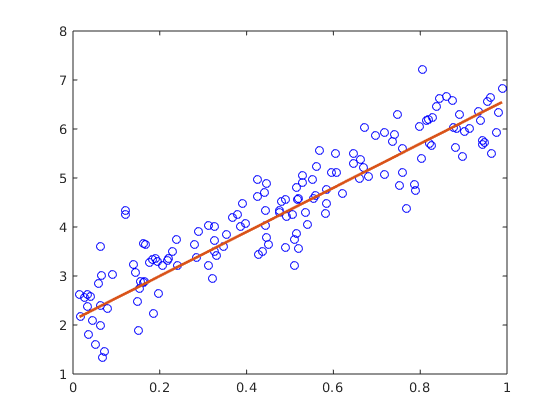

yi = fcn(xi) + ei; % virtual "measurements" contain error

cla
plot(xi, yi,'ob')
hold on
plot(xi, fcn(xi), 'linewidth', 2)
hold off

### Perform Regression

% pretend that we no longer know the 'real' line
% we still have the data points

% calculate coefficients for the equation system
n_xi = sum(xi);
n_yi = sum(yi);
n_xi2 = sum(xi.^2);
n_xiyi = sum(xi.*yi);

%
A = [[n, n_xi];[n_xi, n_xi2]]

A =   150.0000   73.5741
   73.5741   48.7776


b = [n_yi; n_xiyi]

b =   658.2115
  376.6314


a = A\b;
a0 = a(1)

a0 = 2.3093

a1 = a(2)

a1 = 4.2382

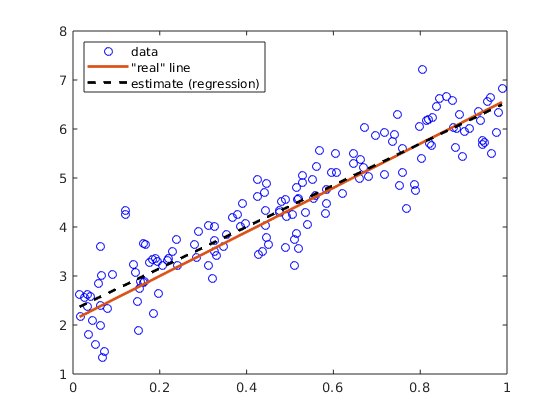


cla
plot(xi, yi,'ob')
hold on
plot(xi, fcn(xi), 'linewidth', 2)
plot(xi, a0+xi*a1, 'k--', 'linewidth', 2)
legend('data', '"real" line', 'estimate (regression)', ...
    'location', 'northwest')

### Add standard error of the estimate


Sr = sum((yi - (a0+xi*a1)).^2)

Sr = 40.9087

St = sum((yi - mean(yi)).^2)

St = 268.8516

s_yx = sqrt(Sr/(n-2))

s_yx = 0.5257

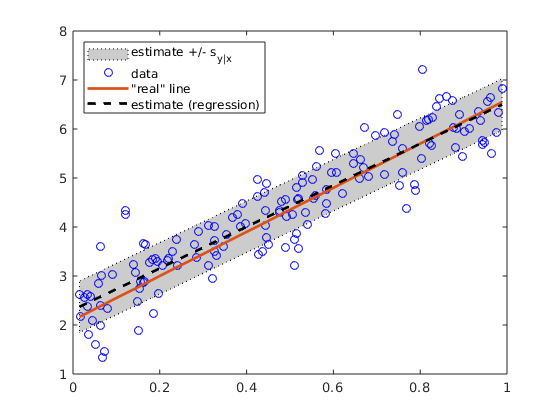


cla
% shade the area within the standard error of the estimate
% (lecture used lines) ... 
% plotting first so everything else is plotted on top
fill([xi; flip(xi)], [a0+xi*a1+s_yx; flip(a0+xi*a1-s_yx)], ...
    [.8, .8, .8], 'linestyle', ':')
plot(xi, yi,'ob')
hold on
plot(xi, fcn(xi), 'linewidth', 2)
plot(xi, a0+xi*a1, 'k--', 'linewidth', 2)
legend('estimate +/- s_{y|x}', ...
    'data', '"real" line', 'estimate (regression)', ...
    'location', 'northwest')


r2 = 1-Sr/St

r2 = 0.8478